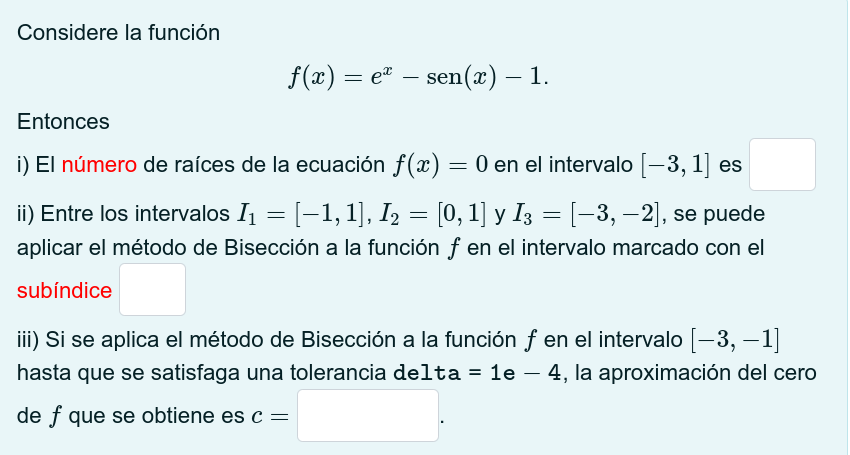

format short
syms f(x)
f(x) = exp(x)- sin(x)-1

$$f(x) = {\mathrm{e}}^{x}-\sin\left(x\right)-1$$

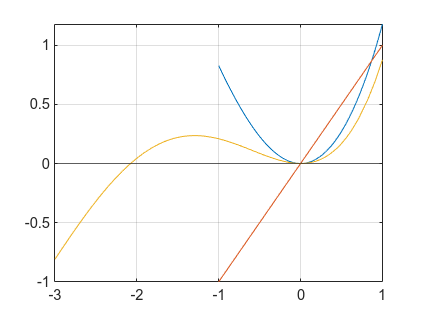


fplot(f,[-3 1])
yline(0)


[c, err, yc] = bisect (f, -3, 1, 1e-4)

c = -2.0768

err = 6.1035e-05

$$yc = {\mathrm{e}}^{-\frac{68053}{32768}}+\sin\left(\frac{68053}{32768}\right)-1$$

double(c)

ans = -2.0768

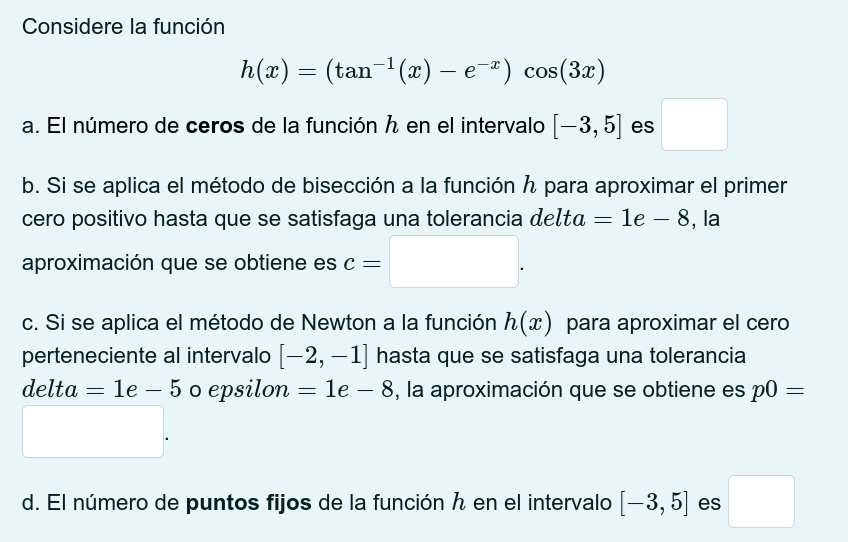

clear 
clf
format short
syms f(x)
f(x) = (atan(x)-exp(-x))*cos(3*x)

$$f(x) = -\cos\left(3\,x\right)\,\left({\mathrm{e}}^{-x}-\mathrm{atan}\left(x\right)\right)$$

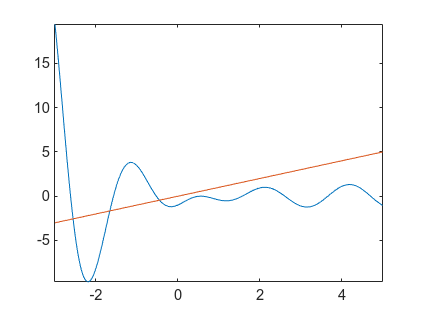


fplot(f,[-3 5])
hold on

fplot(x,[-3 5])



[c] = bisect (f, 0.4, 0.6, 1e-8)

c = 0.5236

double(c)

ans = 0.5236

df = diff(f(x))

$$df = 3\,\sin\left(3\,x\right)\,\left({\mathrm{e}}^{-x}-\mathrm{atan}\left(x\right)\right)+\cos\left(3\,x\right)\,\left({\mathrm{e}}^{-x}+\frac{1}{x^{2}+1}\right)$$


f = matlabFunction(f)

f = function_handle with value:
    @(x)-cos(x.*3.0).*(exp(-x)-atan(x))


df = matlabFunction(df)

df = function_handle with value:
    @(x)sin(x.*3.0).*(exp(-x)-atan(x)).*3.0+cos(x.*3.0).*(exp(-x)+1.0./(x.^2+1.0))



[p0, err, k, y] = newton (f, df, -1.5, 1e-5, 1e-8, 100)

p0 = -1.5708

err = 7.8558e-10

k = 4

y = -4.0961e-15

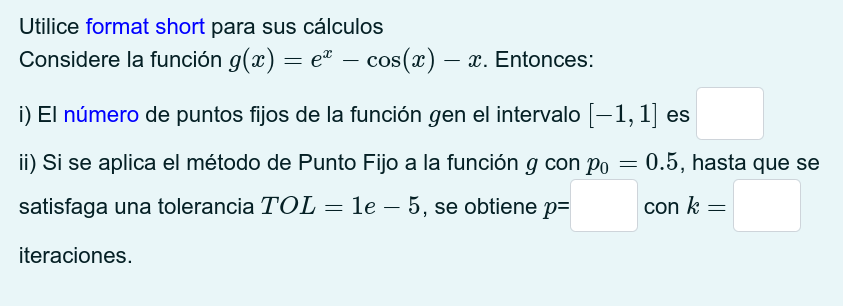

clear 
clf
format short
syms f(x)
f(x) = exp(x) - cos(x) -x

$$f(x) = {\mathrm{e}}^{x}-\cos\left(x\right)-x$$

f = matlabFunction(f(x))

f = function_handle with value:
    @(x)-x-cos(x)+exp(x)


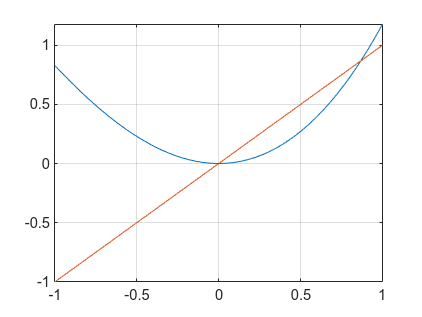


fplot(f,[-1 1])
hold on
grid on
fplot(x,[-1 1])



[p, k, err, P] = fixpt (f, 0.5, 1e-5, 100)

p = 0

k = 7

err = 1.2830e-09

P =     0.2711
    0.0769
    0.0060
    0.0000
    0.0000
         0


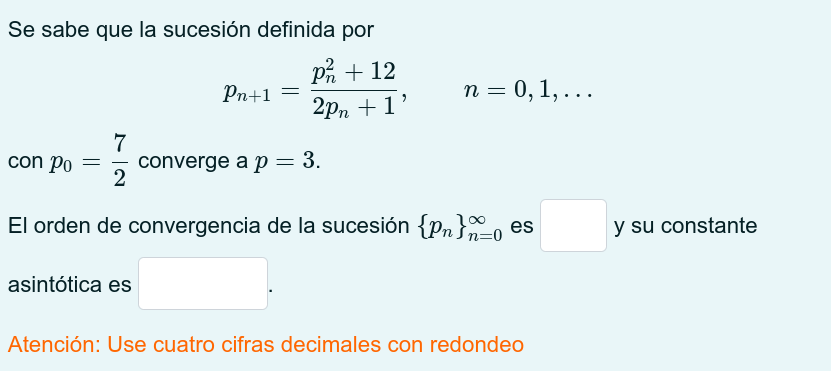

clear
syms n
pn(n) = (n^2 + 12)/(2*n + 1)

$$pn(n) = \frac{n^{2}+12}{2\,n+1}$$


alpha = 1

alpha = 1


err(n) = abs(n - 3)/abs(pn(n) - 3)^alpha

$$err(n) = \frac{\left|n-3\right|}{\left|\frac{n^{2}+12}{2\,n+1}-3\right|}$$


limit(err,3)

$$ans = \infty$$